% Function to add noise and augment data 
function augmentedData = augmentWithNoisePosition(data, desiredRows, noiseFactor)
    currentRows = height(data);
    augmentedData = data;  
    
    while height(augmentedData) < desiredRows
        % Add Gaussian noise to each axis (X, Y, Z)
        noiselatitude = noiseFactor * randn(size(data.latitude));
        noiselongitude = noiseFactor * randn(size(data.longitude));
        noisealtitude = noiseFactor * randn(size(data.altitude));
        noisespeed = noiseFactor * randn(size(data.speed));
        noisecourse = noiseFactor * randn(size(data.course));
        noisehacc = noiseFactor * randn(size(data.hacc));

        % Create noisy copy of the original data
        noisyData = data;
        noisyData.altitude = data.altitude + noiselatitude;
        noisyData.longitude = data.longitude + noiselongitude;
        noisyData.altitude = data.altitude + noisealtitude;
        noisyData.speed = data.speed + noisespeed;
        noisyData.course = data.course + noisecourse;
        noisyData.hacc = data.hacc + noisehacc;
        
        
        augmentedData = [augmentedData; noisyData];
        
        
        if height(augmentedData) > desiredRows
            
            augmentedData = augmentedData(1:desiredRows, :);
        end
    end
end

function augmentedData = augmentWithNoise(data, desiredRows, noiseFactor)
    currentRows = height(data);
    augmentedData = data;  
    
    while height(augmentedData) < desiredRows
        % Add Gaussian noise to each axis (X, Y, Z)
        noiseX = noiseFactor * randn(size(data.X));
        noiseY = noiseFactor * randn(size(data.Y));
        noiseZ = noiseFactor * randn(size(data.Z));
        
        % Create noisy copy of the original data
        noisyData = data;
        noisyData.X = data.X + noiseX;
        noisyData.Y = data.Y + noiseY;
        noisyData.Z = data.Z + noiseZ;
        
        
        augmentedData = [augmentedData; noisyData];
        
        
        if height(augmentedData) > desiredRows
            
            augmentedData = augmentedData(1:desiredRows, :);
        end
    end
end

Data Preprocessing

clc;clear;
load("ActivityLogs.mat");
load("ExampleData.mat");

% Data augmentation

% Parameters
desiredRows = 2174;     % Target number of rows for all datasets
noiseFactor = 0.02;     % Noise factor for adding Gaussian noise

runAccelerationAugmented = augmentWithNoise(runAcceleration, desiredRows, noiseFactor);
sitAccelerationAugmented = augmentWithNoise(sitAcceleration, desiredRows, noiseFactor);
walkAccelerationAugmented = augmentWithNoise(walkAcceleration, desiredRows, noiseFactor);

runAccelerationAugmented.Activity = repmat("Run", height(runAccelerationAugmented), 1);
sitAccelerationAugmented.Activity = repmat("Sit", height(sitAccelerationAugmented), 1);
walkAccelerationAugmented.Activity = repmat("Walk", height(walkAccelerationAugmented), 1);
unknownAcceleration.Activity = repmat("Unknown", height(unknownAcceleration), 1);

combinedData = [runAccelerationAugmented; sitAccelerationAugmented; walkAccelerationAugmented; unknownAcceleration];

combinedData = combinedData(randperm(height(combinedData)), :);

disp(combinedData(1:10,:));

           Timestamp               X          Y          Z        Activity 
    ________________________    _______    _______    ________    _________

    21-Jul-2023 15:36:39.369    -5.3198    -17.774      5.0263    "Run"    
    21-Jul-2023 15:35:27.821    -2.8411    -8.4804    -0.84831    "Walk"   
    21-Jul-2023 15:35:37.005    -1.2433    -11.461     0.13742    "Walk"   
    20-Jul-2023 13:35:00.484     1.4991     2.7812       9.209    "Sit"    
    26-Jul-2023 13:30:08.044    -7.4077    -2.0446     -6.2632    "Unknown"
    21-Jul-2023 15:35:34.061      -4.45    -12.982    -0.56499    "Walk"   
    21-Jul-2023 15:35:21.741    -1.5531    -8.3486    -0.73242    "Walk"   
    26-Jul-2023 13


save('finalAugmentedData.mat', 'combinedData');

PositionAugmented = augmentWithNoisePosition(Position, height(Acceleration), noiseFactor);

Acceleration = table2array(Acceleration);
PositionAugmented = table2array(PositionAugmented);

augmentedPosAcc = [Acceleration,PositionAugmented];


Data Visualization

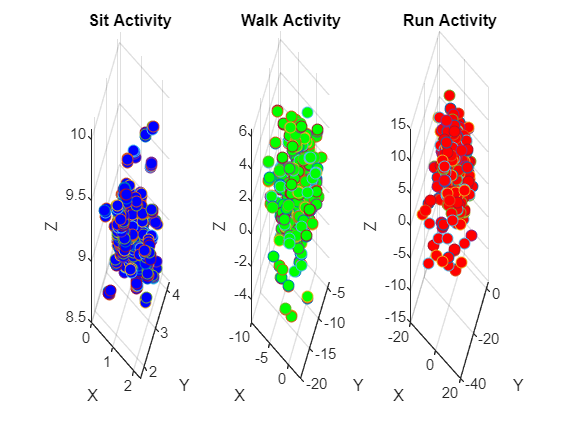


x = combinedData.X;
y = combinedData.Y;
z = combinedData.Z;
activities = combinedData.Activity;  % Activity labels

% Convert activities to a numeric value for color mapping
activity_map = containers.Map({'Sit', 'Walk', 'Run', 'Unknown'}, [1, 2, 3, 4]);
activity_codes = arrayfun(@(a) activity_map(char(a)), activities);

% Color map
colors = [0, 0, 1;  % Blue for Sit
          0, 1, 0;  % Green for Walk
          1, 0, 0;  % Red for Run
          0.5, 0.5, 0.5];  % Gray for Unknown


figure;

% Subplot 1: Plot for Sit
subplot(1, 3, 1);
hold on;
for i = 1:length(x)
    if strcmp(activities{i}, 'Sit')
        plot3(x(i), y(i), z(i), 'o', 'MarkerSize', 6, 'MarkerFaceColor', colors(1, :));
    end
end
hold off;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Sit Activity');
view(30, 30);
grid on;

% Subplot 2: Plot for Walk
subplot(1, 3, 2);
hold on;
for i = 1:length(x)
    if strcmp(activities{i}, 'Walk')
        plot3(x(i), y(i), z(i), 'o', 'MarkerSize', 6, 'MarkerFaceColor', colors(2, :));
    end
end
hold off;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Walk Activity');
view(30, 30);
grid on;

% Subplot 3: Plot for Run
subplot(1, 3, 3);
hold on;
for i = 1:length(x)
    if strcmp(activities{i}, 'Run')
        plot3(x(i), y(i), z(i), 'o', 'MarkerSize', 6, 'MarkerFaceColor', colors(3, :));
    end
end
hold off;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Run Activity');
view(30, 30);

grid on;

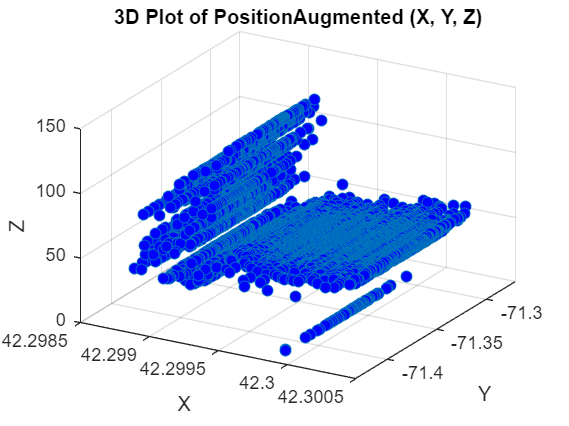


x1 = PositionAugmented(:,1);
y1 = PositionAugmented(:,2);
z1 = PositionAugmented(:,3);

figure;

% 3D plot of X, Y, Z coordinates
subplot(1, 1, 1);
hold on;
plot3(x1, y1, z1, 'o', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
hold off;

xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Plot of PositionAugmented (X, Y, Z)');
view(30, 30);
grid on;

Some more analysis

meanAccelX = mean(runAccelerationAugmented.X);
meanAccelY = mean(runAccelerationAugmented.Y);
meanAccelZ = mean(runAccelerationAugmented.Z);

% Standard deviation of acceleration
stdAccelX = std(runAccelerationAugmented.X);
stdAccelY = std(runAccelerationAugmented.Y);
stdAccelZ = std(runAccelerationAugmented.Z);

% Root mean square (RMS) of acceleration
rmsAccelX = rms(runAccelerationAugmented.X);
rmsAccelY = rms(runAccelerationAugmented.Y);
rmsAccelZ = rms(runAccelerationAugmented.Z);

Develop The Model

% Define the rest thresholds
timeThreshold = 600;  % 10 minutes in seconds
distanceThreshold = 2000;  % 2 kilometers in meters

% Initialize the labels vector
labels = zeros(height(runAccelerationAugmented), 1);  % Start with 0 (no rest needed)

% Compute features for each row in the augmented runAcceleration data
features = zeros(height(runAccelerationAugmented), 8);  % 8 features for each session

for i = 1:height(runAccelerationAugmented)
    % Calculate the total running time for this session
    % Ensure that i:i+1 does not exceed the bounds (use only the current row i)
    if i > 1
        timeDiff = seconds(runAccelerationAugmented.Timestamp(i) - runAccelerationAugmented.Timestamp(i-1));
    else
        timeDiff = 0;  % Set to zero for the first row as there is no previous row
    end
    totalRunningTime = timeDiff;
    
    % Estimate total distance covered during this session (use only the current row i)
    dt = timeDiff;  % Time difference (consider this row only for simplicity)
    velocityX = runAccelerationAugmented.X(i) * dt;
    velocityY = runAccelerationAugmented.Y(i) * dt;
    velocityZ = runAccelerationAugmented.Z(i) * dt;
    distanceTraveled = sqrt(velocityX.^2 + velocityY.^2 + velocityZ.^2);
    totalDistance = distanceTraveled;
    
    % Check if the session exceeds the rest thresholds
    if totalRunningTime >= timeThreshold || totalDistance >= distanceThreshold
        labels(i) = 1;  % Rest needed
    else
        labels(i) = 0;  % No rest needed
    end
    
    % Compute features (mean and standard deviation of acceleration) for this row
    meanAccelX = runAccelerationAugmented.X(i);
    meanAccelY = runAccelerationAugmented.Y(i);
    meanAccelZ = runAccelerationAugmented.Z(i);
    
    stdAccelX = std(runAccelerationAugmented.X(i));  % For a single row, std will be 0
    stdAccelY = std(runAccelerationAugmented.Y(i));
    stdAccelZ = std(runAccelerationAugmented.Z(i));
    
    % Combine features for this row
    features(i, :) = [meanAccelX, meanAccelY, meanAccelZ, stdAccelX, stdAccelY, stdAccelZ, totalRunningTime, totalDistance];
end

% Normalize the features
featuresNormalized = (features - mean(features)) ./ std(features);

% Train a logistic regression model using the features and labels
mdl = fitctree(featuresNormalized, labels);

% Predict whether to rest on new data (for the same features)
predictedLabel = round(predict(mdl, featuresNormalized));

% Evaluate the model by comparing predicted labels with actual labels
accuracy = sum(predictedLabel == labels) / length(labels);
fprintf('Logistic regression model Model Accuracy: %.2f%%\n', accuracy * 100);

Logistic regression model Model Accuracy: 100.00%



cv = cvpartition(size(features, 1), 'HoldOut', 0.2);
idxTrain = training(cv);
idxTest = test(cv);

featuresTrain = features(idxTrain, :);
labelsTrain = labels(idxTrain);

featuresTest = features(idxTest, :);
labelsTest = labels(idxTest);

% Step 2: Train a classification model (e.g., Random Forest)
mdl = fitcensemble(featuresTrain, labelsTrain, 'Method', 'Bag', 'Learners', 'tree');

% Step 3: Predict the labels for the test data
predictedLabels = predict(mdl, featuresTest);

% Step 4: Evaluate the model's performance
accuracy = sum(predictedLabels == labelsTest) / length(labelsTest);
fprintf('Random Forest Model Accuracy: %.2f%%\n', accuracy * 100);

Random Forest Model Accuracy: 100.00%




confMat = confusionmat(labelsTest, predictedLabels);
disp(confMat);

   434



## Results

We can see that even if we have a large amount of data, this alone cannot be enough in order to make a model that can predict some labels. The current work was made for data analysis purposes! The 100% accuracy should be excelent but in the real world analysis the 100% could mean that there's an overfitting possibility and in our case it is most likely.